# signal definitions


syms tc fc dfdt_c;
fc = sin(tc)

$$fc = \sin\left(\mathrm{tc}\right)$$

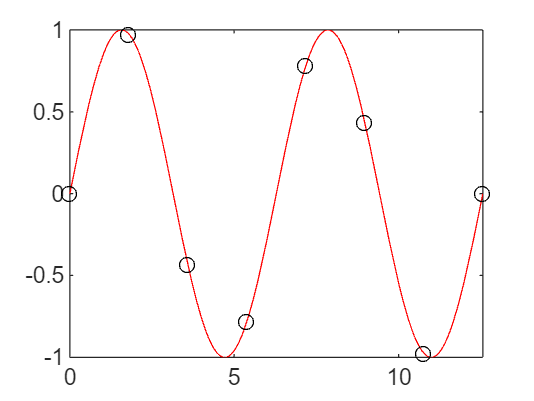


nt = 8;
td = linspace(0,4*pi,nt);
fd = sin(td);

figure(1)
fplot(fc,[0, 4*pi],'r-')
hold on;
plot(td,fd,'ko')

## obtaining derivatives

dfdt_c = diff(fc,tc)

$$dfdt\_c = \cos\left(\mathrm{tc}\right)$$

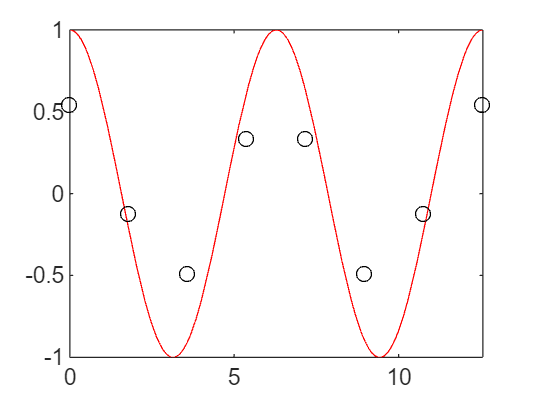


% sampling time period
T = td(2)-td(1);

dfdt_d = gradient(fd,T);

close all;
figure(2)
fplot(dfdt_c,[0, 4*pi],'r-')
hold on
plot(td,dfdt_d,'ko')